# RVC2: Chapter 7

format compact
close all
clear
clc

## 7.1.1  Planar (2D) robotic arms

import ETS2.*
a1 = 1;
E = Rz('q1') * Tx(a1)

ETS2 constructing Rz
ETS2 constructing Tx
ETS2 constructing Rz
E = 
Rz(q1)Tx(1)



E.fkine( 30, 'deg')


ans = 
    0.8660   -0.5000     0.866
    0.5000    0.8660       0.5
         0         0         1



%BUG E.teach

a1 = 1; a2 = 1;
E = Rz('q1') * Tx(a1) * Rz('q2') * Tx(a2)

ETS2 constructing Rz
ETS2 constructing Tx
ETS2 constructing Rz
ETS2 constructing Rz
ETS2 constructing Tx
ETS2 constructing Rz
E = 
Rz(q1)Tx(1)Rz(q2)Tx(1)



E.fkine( [30, 40], 'deg')


ans = 
    0.3420   -0.9397     1.208
    0.9397    0.3420      1.44
         0         0         1



%BUG E.plot( [30, 40], 'deg')

E.structure

ans = RR


a1 = 1;
%BUG E = Rz('q1') * Tx(a1) * Tz('q2')

E.structure

ans = RR

## 7.1.2  3-dimensional robotic arms

import ETS3.*
L1 = 0; L2 = -0.2337; L3 = 0.4318; L4 = 0.0203; L5 = 0.0837; L6 = 0.4318;
E3 = Tz(L1) * Rz('q1') * Ry('q2') * Ty(L2) * Tz(L3) * Ry('q3') ...
* Tx(L4) * Ty(L5) * Tz(L6) * Rz('q4') * Ry('q5') * Rz('q6');

ETS3 constructing Tz
ETS2 constructing Rz
ETS3 constructing Tz
ETS3 constructing Ry
ETS3 constructing Tz
ETS2 constructing Ty
ETS3 constructing Tz
ETS3 constructing Tz
ETS3 constructing Ry
ETS3 constructing Tz


ETS2 constructing Tx
ETS3 constructing Tz
ETS2 constructing Ty
ETS3 constructing Tz
ETS3 constructing Tz
ETS2 constructing Rz
ETS3 constructing Tz
ETS3 constructing Ry
ETS3 constructing Tz
ETS2 constructing Rz
ETS3 constructing Tz



%BUG E3.fkine([0 0 0 0 0 0])

## 7.1.2.1 Denavit-Hartenberg parameters

L = Revolute('a', 1)

L = 
Revolute(std): theta=q, d=0, a=1, alpha=0, offset=0



L.A(0.5)


ans = 
    0.8776   -0.4794         0    0.8776
    0.4794    0.8776         0    0.4794
         0         0         1         0
         0         0         0         1



L.type

ans = R


L.a

ans = 1


L.offset = 0.5;
L.A(0)


ans = 
    0.8776   -0.4794         0    0.8776
    0.4794    0.8776         0    0.4794
         0         0         1         0
         0         0         0         1



robot = SerialLink( [ Revolute('a', 1) Revolute('a', 1) ], ...
'name', 'my robot')

robot = 
my robot:: 2 axis, RR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+



robot.fkine([30 40], 'deg')


ans = 
    0.3420   -0.9397         0     1.208
    0.9397    0.3420         0      1.44
         0         0         1         0
         0         0         0         1



models

ABB, IRB140, 6DOF, modified_DH (mdl_irb140_mdh)
ABB, IRB140, 6DOF, standard_DH (mdl_irb140)
ABB, S4_2.8, S4 2.8m reach version, 6DOF, standard_DH (mdl_S4ABB2p8)
Adept, Cobra600, 4DOF, standard_DH (mdl_cobra600)
Aldebaran, NAO, humanoid, 4DOF, standard_DH (mdl_nao)
Baxter, Rethink Robotics, 7DOF, standard_DH (mdl_baxter)
Fanuc, AM120iB/10L, 6DOF, standard_DH (mdl_fanuc10l)
Fanuc, M16, 6DOF, standard_DH (mdl_m16)
Kinova, Jaco, 6DOF, standard_DH (mdl_jaco)
Kinova, Mico, 6DOF, standard_DH (mdl_mico)
Kuka, KR5, 6DOF, standard_DH (mdl_KR5)
Motoman, HP6, 6DOF, standard_DH (mdl_motomanHP6)
Stanford, Stanford Arm, prismatic, 6DOF, standard_DH (mdl_stanford)
Stanford, Stanford arm, prismatic, 6DOF, modified_DH (mdl_stanford_mdh)
Trossen Robotics, PhantomX Pincher, 4DOF, standard_DH (mdl_phantomx)
Unimation, Puma560, dynamics, 6DOF, modified_DH (mdl_puma560akb)
Unimation, Puma560, dynamics, 6DOF, standard_DH (mdl_puma560)
Unimation, Puma560, on XY base, redundant, 8DOF, standard_DH (mdl_p8)
gener

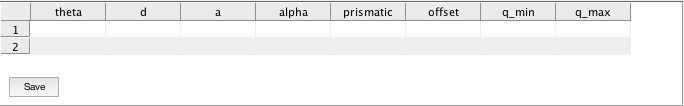


mdl_irb140

robot.edit

pause(5)
delete(1)  % close the edit window

## 7.1.2.2 Product of exponentials

a1 = 1; a2 = 1;
TE0 = SE2(a1+a2, 0, 0);

S1 = Twist( 'R', [0 0] );
S2 = Twist( 'R', [a1 0] );

%BUG TE = S1.T(30, 'deg') * S2.T(40, 'deg') *TE0

## 7.1.2.3 6-axis industrial robot

mdl_puma560

p560

p560 = 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+



TE = p560.fkine(qz)


TE = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1



p560.tool = SE3(0, 0, 0.2);

p560.fkine(qz)


ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.6318
         0         0         0         1



p560.base = SE3(0, 0, 30*0.0254);
p560.fkine(qz)


ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1     1.394
         0         0         0         1



p560.base = SE3(0,0,3) * SE3.Rx(pi);
p560.fkine(qz)


ans = 
         1         0         0    0.4521
         0        -1         0      0.15
         0         0        -1     2.368
         0         0         0         1



q=jtraj(qz, qr, 8);
q

q =          0         0         0         0         0         0
         0    0.0365   -0.0365         0         0         0
         0    0.2273   -0.2273         0         0         0
         0    0.5779   -0.5779         0         0         0
         0    0.9929   -0.9929         0         0         0
         0    1.3435   -1.3435         0         0         0
         0    1.5343   -1.5343         0         0         0
         0    1.5708   -1.5708         0         0         0



T = p560.fkine(q);

about(T)

T [SE3] : 1x8 (1.0 kB)



T(4)


ans = 
         1         0         0     0.382
         0        -1         0      0.15
         0         0        -1     2.132
         0         0         0         1


## 7.2  Inverse kinematics

## 7.2.1.1  Closed-form solution

import ETS2.*
a1 = 1; a2 = 1;
E = Rz('q1') * Tx(a1) * Rz('q2') * Tx(a2)

ETS2 constructing Rz
ETS2 constructing Tx
ETS2 constructing Rz
ETS2 constructing Rz
ETS2 constructing Tx
ETS2 constructing Rz
E = 
Rz(q1)Tx(1)Rz(q2)Tx(1)



syms q1 q2 real

TE = E.fkine( [q1, q2] )

$$\left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$


syms x y real

e1 = x == TE.t(1)

$$e1 = x=\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)$$

e2 = y == TE.t(2)

$$e2 = y=\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)$$


[s1,s2] = solve( [e1 e2], [q1 q2] )

$$s1 = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{2\,y+\sigma_{2}+\sigma_{1}}{x^{2}+2\,x+y^{2}}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{2}-2\,y+\sigma_{1}}{x^{2}+2\,x+y^{2}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{y^{2}\,\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\\ \sigma_{2}=\frac{x^{2}\,\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}} \end{array}$$

$$s2 = \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right)\\ 2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right) \end{array}\right)$$


length(s2)

ans = 2


s2(1)

$$ans = -2\,\mathrm{atan}\left(\frac{\sqrt{-\left(x^{2}+y^{2}\right)\,\left(x^{2}+y^{2}-4\right)}}{x^{2}+y^{2}}\right)$$

## 7.2.1.2  Numerical solution

pstar = [0.6; 0.7];
q = fminsearch( @(q) norm( E.fkine(q).t - pstar ), [0 0] )

q =    -0.2295    2.1833


E.fkine(q).print

t = (0.6, 0.7), theta = 111.9 deg


## 7.2.2  3-dimensional robot arms

## 7.2.2.1  Closed-form solution

mdl_puma560
qn

qn =          0    0.7854    3.1416         0    0.7854         0

T = p560.fkine(qn)


T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


qi = p560.ikine6s(T)

qi =     2.6486   -3.9270    0.0940    2.5326    0.9743    0.3734

p560.fkine(qi)


ans = 
         0         0         1    0.5963
         0         1         0     -0.15
        -1         0         0  -0.01435
         0         0         0         1




qi = p560.ikine6s(T, 'ru')

qi =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000


p560.ikine6s( SE3(3, 0, 0) )

ans =    NaN   NaN   NaN   NaN   NaN   NaN



q = [0 pi/4 pi 0.1 0 0.2];

p560.ikine6s(p560.fkine(q), 'ru')

ans =    -0.0000    0.7854    3.1416   -3.0409    0.0000   -2.9423


q(4)+q(6)

ans = 0.3000

## 7.2.2.2  Numerical solution

T = p560.fkine(qn)


T = 
         0         0         1    0.5963
         0         1         0   -0.1501
        -1         0         0  -0.01435
         0         0         0         1


qi = p560.ikine(T)

qi =    -0.0000   -0.8335    0.0940    0.0000   -0.8312   -0.0000


qn

qn =          0    0.7854    3.1416         0    0.7854         0


p560.fkine(qi)


ans = 
    0.0000   -0.0000         1    0.5963
   -0.0000         1    0.0000   -0.1501
        -1   -0.0000    0.0000  -0.01435
         0         0         0         1


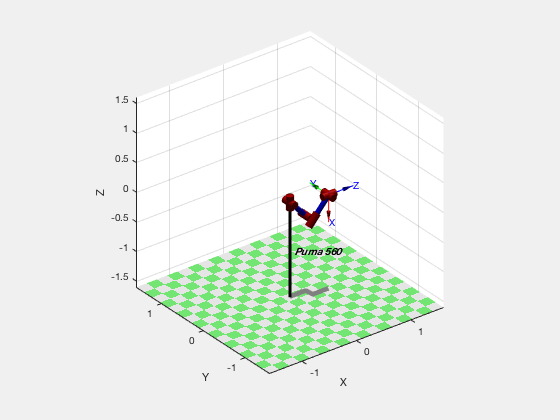


p560.plot(qi)


qi = p560.ikine(T, 'q0', [0 0 3 0 0 0])

qi =    -0.0000    0.7854    3.1416   -0.0000    0.7854    0.0000

## 7.2.2.3  Under-actuated manipulator

mdl_cobra600

c600

c600 = 
Cobra600 [Adept]:: 4 axis, RRPR, stdDH, slowRNE                                   
+---+-----------+-----------+-----------+-----------+-----------+                 
| j |     theta |         d |         a |     alpha |    offset |                 
+---+-----------+-----------+-----------+-----------+-----------+                 
|  1|         q1|      0.387|      0.325|          0|          0|                 
|  2|         q2|          0|      0.275|    3.14159|          0|                 
|  3|          0|         q3|          0|          0|0          || 37|        11g|
|  4|         q4|          0|          0|          0|          0|                 
+---+-----------+-----------+-----------+-----------+-----------+                 



T = SE3(0.4, -0.3, 0.2) * SE3.rpy(30, 40, 160, 'xyz', 'deg');

q = c600.ikine(T, 'mask', [1 1 1 0 0 1])

q =    -0.1110   -1.1760    0.1870   -0.8916


Ta = c600.fkine(q);
Ta.print('xyz')

t = (0.4, -0.3, 0.2), RPY/xyz = (22.7, 0, 180) deg


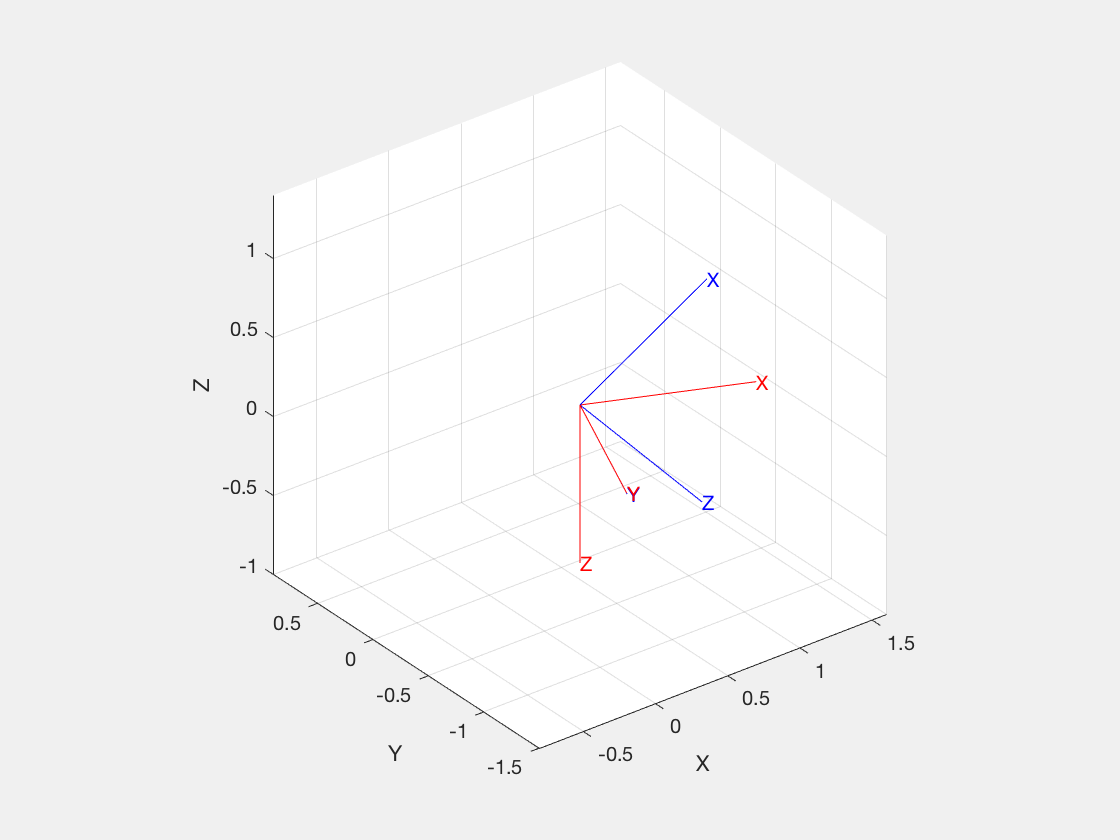


TT = c600.fkine(q);
clf
trplot(T, 'color', 'b')
hold on 
trplot(Ta, 'color', 'r')
hold off

## 7.2.2.4  Redundant manipulator

mdl_baxter

left

left = 
Baxter LEFT [Rethink Robotics]:: 7 axis, RRRRRRR, stdDH, slowRNE 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.27|      0.069|    -1.5708|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|         q3|      0.364|      0.069|    -1.5708|          0|
|  4|         q4|          0|          0|     1.5708|          0|
|  5|         q5|      0.374|       0.01|    -1.5708|          0|
|  6|         q6|          0|          0|     1.5708|          0|
|  7|         q7|       0.28|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (0.0646, 0.259, 0.119), RPY/zyx = (45, 0, 0) deg    



TE = SE3(0.8, 0.2, -0.2) * SE3.Ry(pi);

q = left.ikine(TE)

q =     0.0895   -0.0464   -0.4259    0.6980   -0.4248    1.0179    0.2998


left.fkine(q).print

t = (0.8, 0.2, -0.2), RPY/zyx = (-180, -4.2e-10, -180) deg


## 7.3  Trajectories

## 7.3.1  Joint-space motion

T1 = SE3(0.4, 0.2, 0) * SE3.Rx(pi);
T2 = SE3(0.4, -0.2, 0) * SE3.Rx(pi/2);

q1 = p560.ikine6s(T1);
q2 = p560.ikine6s(T2);

t = [0:0.05:2]';

q = mtraj(@tpoly, q1, q2, t);

q = mtraj(@lspb, q1, q2, t);

q = jtraj(q1, q2, t);

[q,qd,qdd] = jtraj(q1, q2, t);

q = p560.jtraj(T1, T2, t)

q =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2629    2.0791    0.5992   -0.0003    0.4634    0.1217
    3.2620    2.0791    0.5992   -0.0027    0.4642    0.1228
    3.2596    2.0791    0.5992   -0.0087    0.4662    0.1257
    3.2551    2.0791    0.5992   -0.0199    0.4700    0.1310
    3.2482    2.0791    0.5992   -0.0373    0.4758    0.1394
    3.2384    2.0791    0.5992   -0.0618    0.4840    0.1512
    3.2255    2.0791    0.5992   -0.0940    0.4949    0.1667
    3.2094    2.0791    0.5992   -0.1344    0.5084    0.1861
    3.1899    2.0791    0.5992   -0.1832    0.5248    0.2096

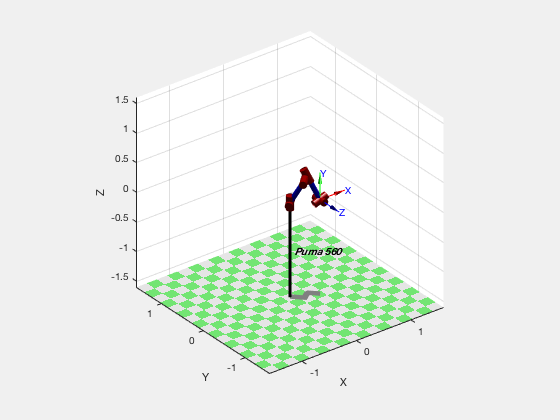


clf
p560.plot(q)

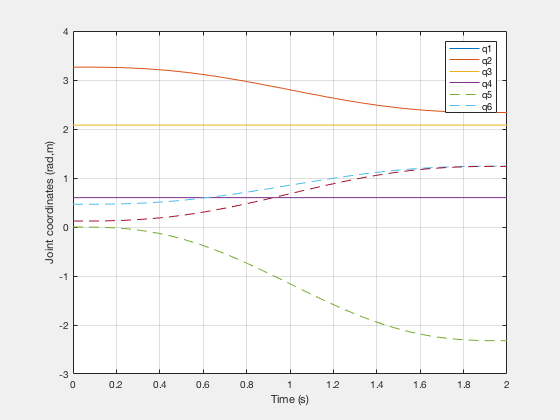


clf
plot(t, q(:,2))

qplot(t, q);


T = p560.fkine(q);

p = T.transl;

about(p)

p [double] : 41x3 (984 bytes)


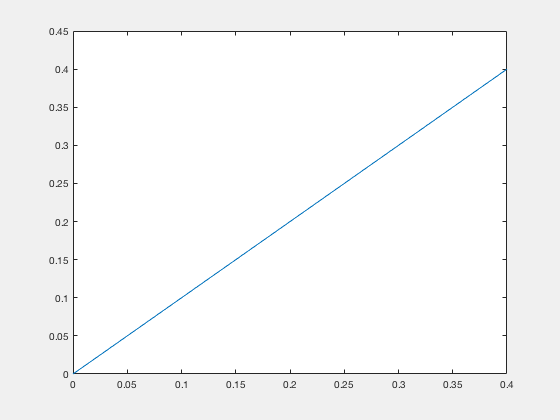


plot(p(1,:), p(2,:))

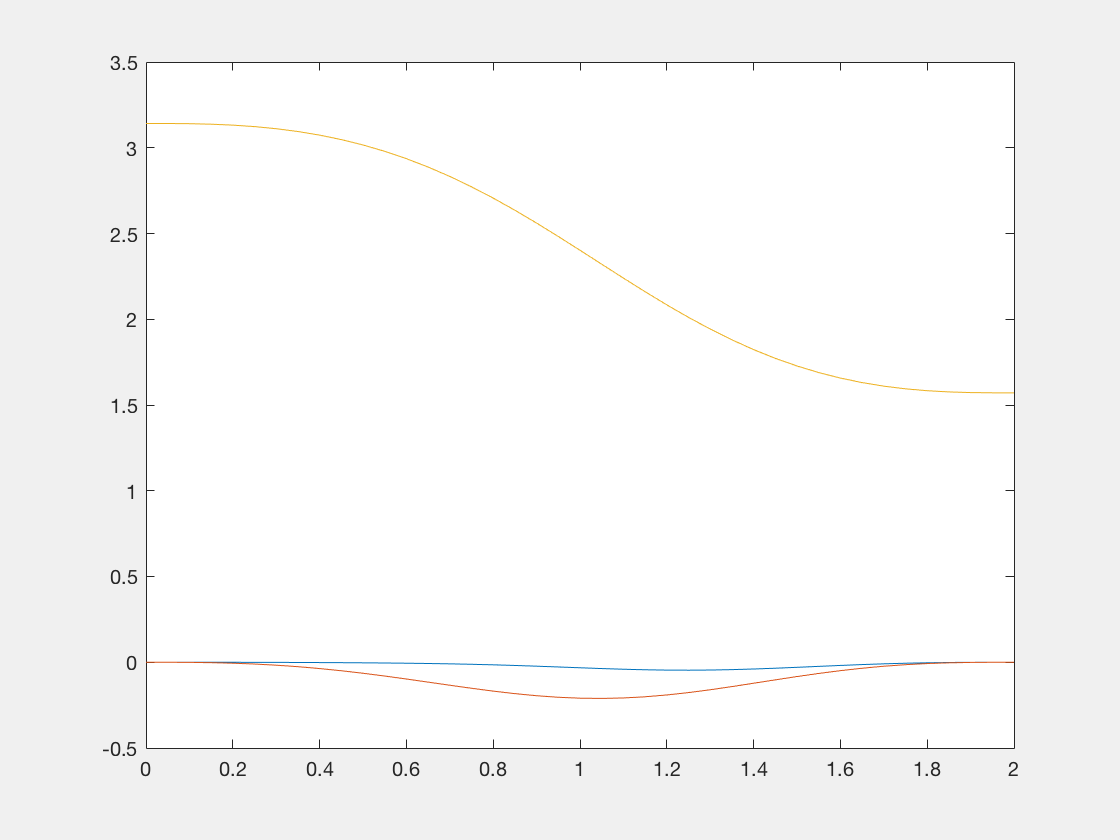


plot(t, T.torpy('xyz'))

## 7.3.2  Cartesian motion

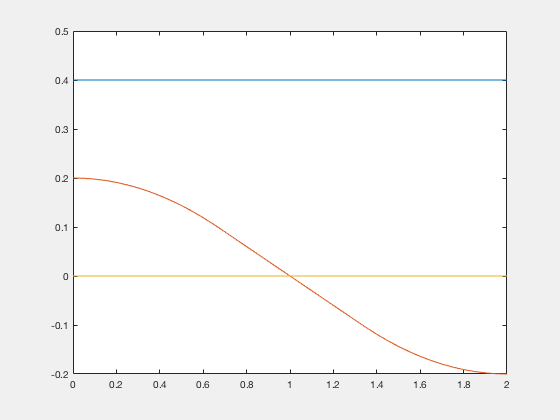

Ts = ctraj(T1, T2, length(t));

plot(t, Ts.transl);

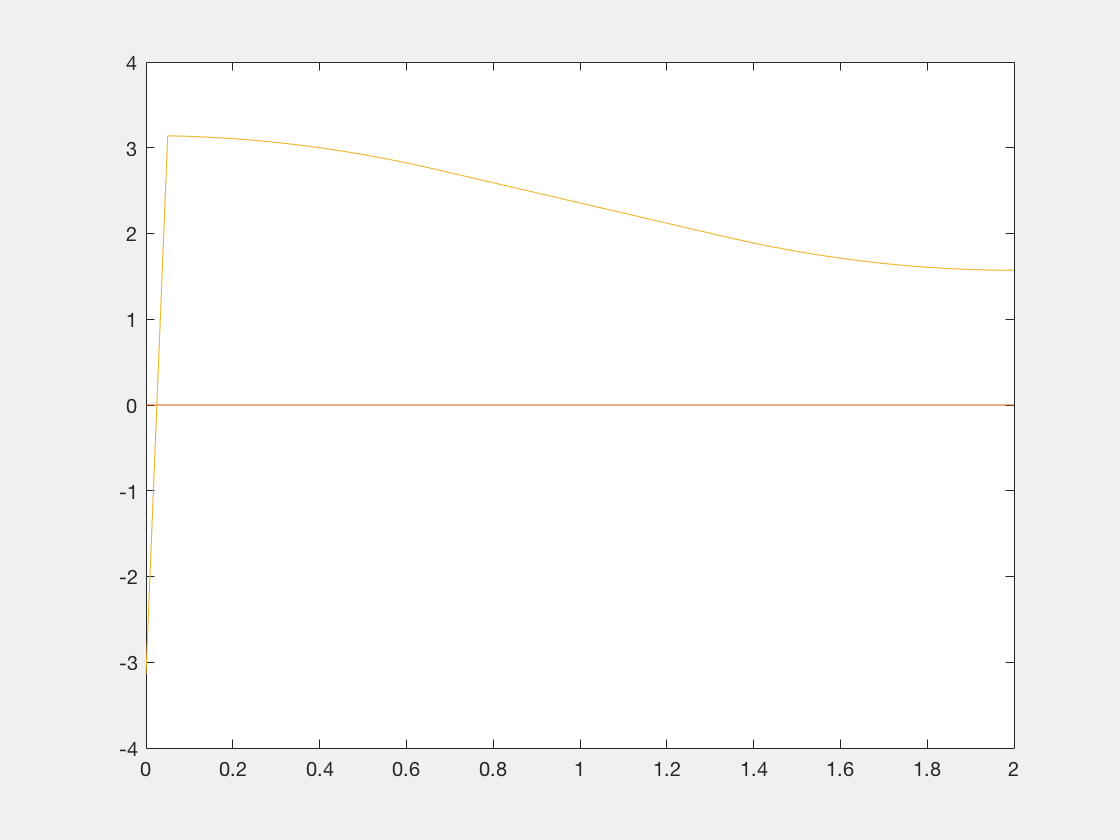


plot(t, Ts.torpy('xyz'));


qc = p560.ikine6s(Ts);

## 7.3.3  Kinematics in Simulink

sl_jspace

## 7.3.4  Mmotion through a singularity

T1 = SE3(0.5, 0.3, 0.44) * SE3.Ry(pi/2);
T2 = SE3(0.5, -0.3, 0.44) * SE3.Ry(pi/2);

Ts = ctraj(T1, T2, length(t));

qc = p560.ikine6s(Ts)

qc =     3.4218    1.8818   -0.3310   -1.5015    0.2808   -1.6429
    3.4203    1.8807   -0.3295   -1.5023    0.2794   -1.6420
    3.4160    1.8774   -0.3252   -1.5048    0.2750   -1.6394
    3.4087    1.8719   -0.3181   -1.5089    0.2677   -1.6350
    3.3985    1.8643   -0.3083   -1.5147    0.2573   -1.6288
    3.3852    1.8548   -0.2960   -1.5224    0.2439   -1.6207
    3.3688    1.8435   -0.2816   -1.5322    0.2274   -1.6104
    3.3492    1.8305   -0.2652   -1.5446    0.2077   -1.5976
    3.3262    1.8162   -0.2473   -1.5604    0.1846   -1.5813
    3.2997    1.8007   -0.2282   -1.5815    0.1581   -1.5599


m = p560.maniplty(qc);

## 7.3.5  Configuration change

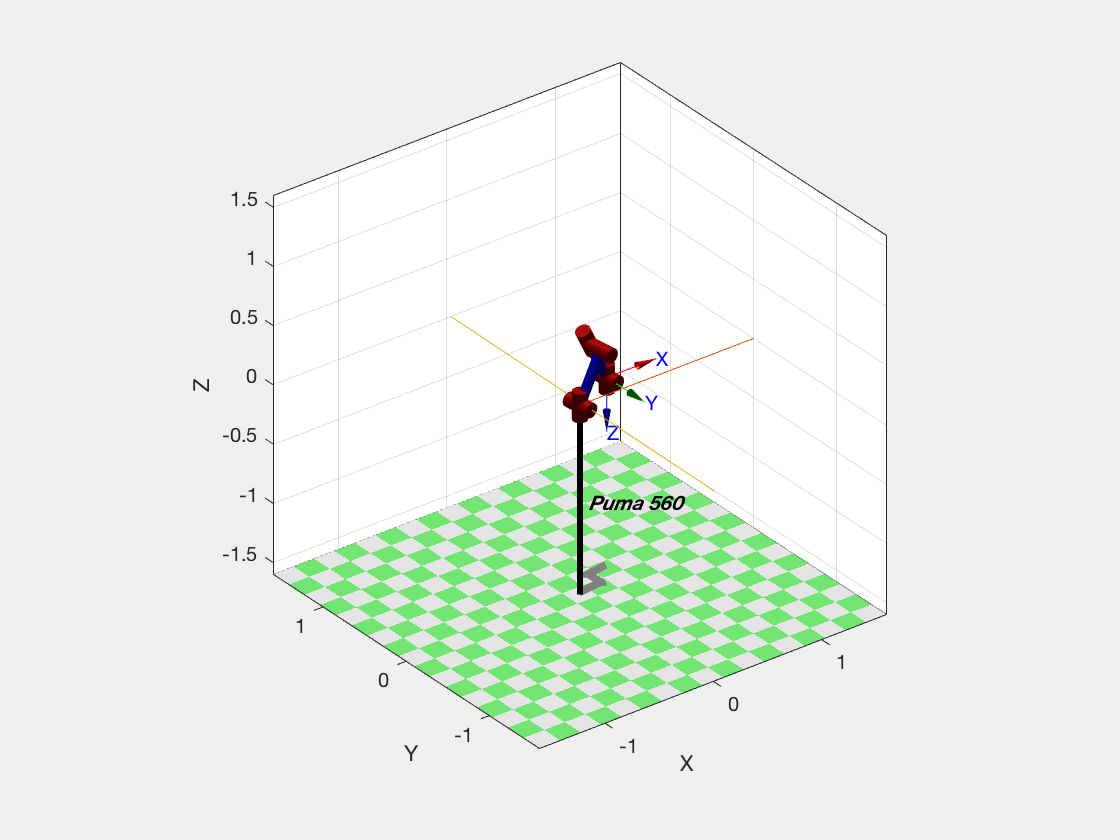

T = SE3(0.4, 0.2, 0) * SE3.Rx(pi);

qr = p560.ikine6s(T, 'ru');
ql = p560.ikine6s(T, 'lu');

q = jtraj(qr, ql, t);

p560.plot(q)

## 7.4.2  Determining DH params

s = 'Tz(L1) Rz(q1) Ry(q2) Ty(L2) Tz(L3) Ry(q3) Tx(L4) Ty(L5) Tz(L6) Rz(q4) Ry(q5) Rz(q6)'

s = Tz(L1) Rz(q1) Ry(q2) Ty(L2) Tz(L3) Ry(q3) Tx(L4) Ty(L5) Tz(L6) Rz(q4) Ry(q5) Rz(q6)


dh = DHFactor(s);

In DHFactor
Tz(L1) Rz(q1) Ry(q2) Ty(L2) Tz(L3) Ry(q3) Tx(L4) Ty(L5) Tz(L6) Rz(q4) Ry(q5) Rz(q6)
Tz(L1).Rz(q1).Ry(q2).Ty(L2).Tz(L3).Ry(q3).Tx(L4).Ty(L5).Tz(L6).Rz(q4).Ry(q5).Rz(q6)
Swap: Tz(L1) <-> Rz(q1)
Swap: Ty(L2) <-> Tz(L3)
Swap: Ty(L2) <-> Ry(q3)
Swap: Ty(L2) <-> Tx(L4)
Swap: Ty(L5) <-> Tz(L6)
Swap: Ty(L2) <-> Tz(L6)
Merge: Ty(L2) Ty(L5) := Ty(L2+L5)
Rz(q1).Tz(L1).Ry(q2).Tz(L3).Ry(q3).Tx(L4).Tz(L6).Ty(L2+L5).Rz(q4).Ry(q5).Rz(q6)
Float: Tz(L6) to Ry(q5)
initial merge + swap
Rz(q1).Tz(L1).Ry(q2).Tz(L3).Ry(q3).Tx(L4).Ty(L2+L5).Rz(q4).Tz(L6).Ry(q5).Rz(q6)
ReplaceToZ: Ry(q2) := Rx(-90)Rz(q2)Rx(+90)
ReplaceToZ: Ry(q3) := Rx(-90)Rz(q3)Rx(+90)
ReplaceToZ: Ry(q5) := Rx(-90)Rz(q5)Rx(+90)
joint vars to Z
Rz(q1).Tz(L1).Rx(-90).Rz(q2).Rx(+90).Tz(L3).Rx(-90).Rz(q3).Rx(+90).Tx(L4).Ty(L2+L5).Rz(q4).Tz(L6).Rx(-90).Rz(q5).Rx(+90).Rz(q6)
0---------------------------------------
Swap: Rx(+90) <-> Tx(L4)
ReplaceY: Rx(+90)Tz(L3) := Ty(-L3)Rx(+90)
ReplaceY: Rx(+90)Ty(L2+L5) := Tz(L2+L5)Rx(+90)
Eliminate


dh

dh =
DH(q1, L1, 0, -90).DH(q2+90, 0, -L3, 0).DH(q3-90, L2+L5, L4, 90).DH(q4, L6, 0, -90).DH(q5, 0, 0, 90).DH(q6, 0, 0, 0)



cmd = dh.command('puma')

cmd =
SerialLink([0, L1, 0, -pi/2, 0; 0, 0, -L3, 0, 0; 0, L2+L5, L4, pi/2, 0; 0, L6, 0, -pi/2, 0; 0, 0, 0, pi/2, 0; 0, 0, 0, 0, 0; ], 'name', 'puma', 'base', eye(4,4), 'tool', eye(4,4), 'offset', [0 pi/2 -pi/2 0 0 0 ])



robot = eval(cmd)

robot = 
puma:: 6 axis, RRRRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        0.1|          0|    -1.5708|          0|
|  2|         q2|          0|    -0.4318|          0|     1.5708|
|  3|         q3|     0.1837|     0.0203|     1.5708|    -1.5708|
|  4|         q4|     0.4318|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+


## 7.4.3  Modfiied Denativ-Hartenberg paramters

L1 = RevoluteMDH('d', 1)

L1 = 
Revolute(mod): theta=q, d=1, a=0, alpha=0, offset=0


## 7.5  Applications

## 7.5.1 Writing on a surface

load hershey

B = hershey{'B'}

B =     stroke: [2×23 double]
     width: 0.8400
       top: 0.8400
    bottom: 0


B.stroke

ans =     0.1600    0.1600       NaN    0.1600    0.5200    0.6400    0.6800    0.7200    0.7200    0.6800    0.6400    0.5200       NaN    0.1600    0.5200    0.6400    0.6800    0.7200    0.7200    0.6800    0.6400    0.5200    0.1600
    0.8400         0       NaN    0.8400    0.8400    0.8000    0.7600    0.6800    0.6000    0.5200    0.4800    0.4400       NaN    0.4400    0.4400    0.4000    0.3600    0.2800    0.1600    0.0800    0.0400         0         0


path = [ 0.25*B.stroke; zeros(1,numcols(B.stroke))];
k = find(isnan(path(1,:)))

k =      3    13

path(:,k) = path(:,k-1); path(3,k) = 0.2;

traj = mstraj(path(:,2:end)', [0.5 0.5 0.5], [], path(:,1)', ...
0.02, 0.2);

about(traj)

traj [double] : 487x3 (11.7 kB)



numrows(traj) * 0.02

ans = 9.7400

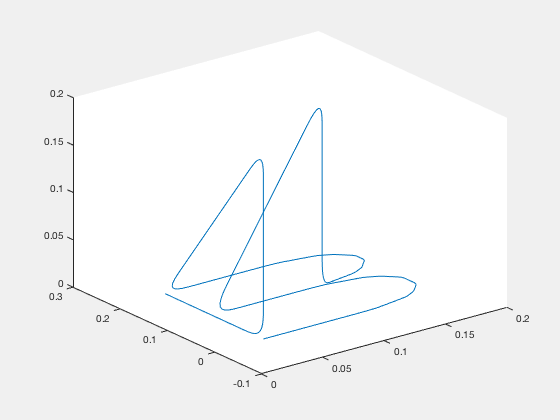


clf
plot3(traj(:,1), traj(:,2), traj(:,3))

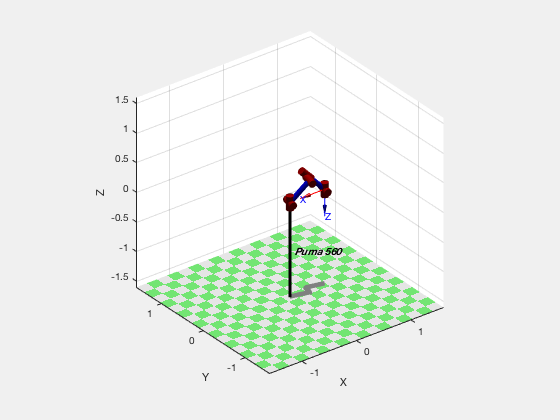


Tp = SE3(0.6, 0, 0) * SE3(traj) * SE3.oa( [0 1 0], [0 0 -1]);

q = p560.ikine6s(Tp);

clf
p560.plot(q)

## 7.5.2  A simple walking robot

close all

s = 'Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)';

dh = DHFactor(s);

INIT: Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
PARSED: Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
initial merge + swap
Rz(q1).Rx(q2).Ty(L1).Rx(q3).Tz(L2)
ReplaceToZ: Rx(q2) := Ry(+90)Rz(q2)Ry(-90)
ReplaceToZ: Rx(q3) := Ry(+90)Rz(q3)Ry(-90)
joint vars to Z
Rz(q1).Ry(+90).Rz(q2).Ry(-90).Ty(L1).Ry(+90).Rz(q3).Ry(-90).Tz(L2)
0---------------------------------------
Swap: Ry(-90) <-> Ty(L1)
Eliminate: Ry(-90) Ry(+90)
ReplaceY: Ry(-90)Tz(L2) := Tx(-L2)Ry(-90)
Rz(q1).Ry(+90).Rz(q2).Ty(L1).Rz(q3).Tx(-L2).Ry(-90)
1---------------------------------------
Rz(q1).Ry(+90).Rz(q2).Ty(L1).Rz(q3).Tx(-L2).Ry(-90)
1---------------------------------------
** deal with Ry/Ty
ReplaceToZ2: Ry(+90) := Rz(+90)Rx(+90)Rz(-90)
ReplaceToZ2: Ty(L1) := Rz(+90)Tx(L1)Rz(-90)
ReplaceToZ2: Ry(-90) := Rz(+90)Rx(-90)Rz(-90)
Merge: Rz(q1) Rz(+90) := Rz(q1+90)
Merge: Rz(-90) Rz(q2) := Rz(q2-90)
Merge: Rz(-90) Rz(q3) := Rz(q3-90)
Merge: Rz(q2-90) Rz(+90) := Rz(q2)
Rz(q1+90).Rx(+90).Rz(q2).Tx(L1).Rz(q3-90


dh.tool

ans =
trotz(pi/2)*trotx(-pi/2)*trotz(-pi/2)



dh.command('leg')

ans =
SerialLink([0, 0, 0, pi/2, 0; 0, 0, L1, 0, 0; 0, 0, -L2, 0, 0; ], 'name', 'leg', 'base', eye(4,4), 'tool', trotz(pi/2)*trotx(-pi/2)*trotz(-pi/2), 'offset', [pi/2 0 -pi/2 ])



L1 = 0.1; L2 = 0.1;
leg = eval( dh.command('leg') )

leg = 
leg:: 3 axis, RRR, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|        0.1|          0|          0|
|  3|         q3|          0|       -0.1|          0|    -1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0), RPY/xyz = (0, -90, 0) deg                


leg

leg = 
leg:: 3 axis, RRR, stdDH, slowRNE                                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|        0.1|          0|          0|
|  3|         q3|          0|       -0.1|          0|    -1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0), RPY/xyz = (0, -90, 0) deg                



transl( leg.fkine([0,0,0]) )

ans =    -0.0000    0.1000    0.1000



leg.plot([0,0,0], 'nobase', 'noshadow', 'notiles')
set(gca, 'Zdir', 'reverse'); view(137,48);

transl( leg.fkine([0.2,0,0]) )

ans =    -0.0199    0.0980    0.1000



transl( leg.fkine([0,0.2,0]) )

ans =    -0.0000    0.0781    0.1179



transl( leg.fkine([0,0,0.2]) )

ans =    -0.0000    0.0801    0.0980



xf = 50; xb = -xf;  y = 50; zu = 20; zd = 50;
path = [xf y zd; xb y zd; xb y zu; xf y zu; xf y zd] * 1e-3;

p = mstraj(path, [], [0, 3, 0.25, 0.5, 0.25]', path(1,:), 0.01, 0);

qcycle = leg.ikine( SE3(p), 'mask', [1 1 1 0 0 0] );

%leg.plot(qcycle, 'loop')
clf
leg.plot(qcycle)

W = 0.1; L = 0.2;

legs(1) = SerialLink(leg, 'name', 'leg1');
legs(2) = SerialLink(leg, 'name', 'leg2', 'base', SE3(-L, 0, 0));
legs(3) = SerialLink(leg, 'name', 'leg3', 'base', SE3(-L, -W, 0) ...
*SE3.Rz(pi));
legs(4) = SerialLink(leg, 'name', 'leg4', 'base', SE3(0, -W, 0) ...
* SE3.Rz(pi));


% k = 1;
% while 1
for k = 1:600
    %q = qleg(p,:);
    legs(1).plot( gait(qcycle, k, 0, false) );
    if k == 1, hold on; end
    legs(2).plot( gait(qcycle, k, 100, false) );
    legs(3).plot( gait(qcycle, k, 200, true) );
    legs(4).plot( gait(qcycle, k, 300, true) );
    drawnow
%    k = k+1;
end

A more polished version of this display is created by the script examples/walking.m